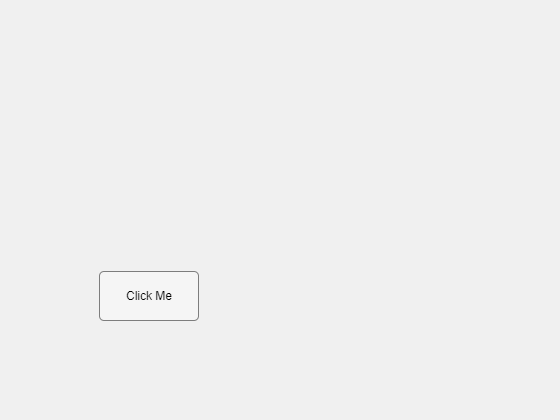

% Create a figure window for the button
fig = uifigure;

function connect()
    comPort = "COM11"; % Replace with your Arduino's COM port
    baudRate = 115200;
    
    if ~exist('o', 'var')
        o = Com(comPort, baudRate);
        mode = 0;
    end
end

% Create the button and set the callback function
btn_d1 = uibutton(fig, 'push', 'Text', 'Click Me', ...
    'Position', [100, 100, 100, 50], ...
    'ButtonPushedFcn', @(btn, event) buttonCallback());


% Define the callback function
function buttonCallback()
    disp('Button clicked!');
    % Add any other actions you want the button to perform here
end